# **Figure 5**

This m-file is written according  to  the paper entitled :

 "**An Efficient Low-Complexity Method to Calculate Hybrid Beamforming Matrices for mmWave Massive MIMO Systems**" 

you can see the paper on this link:  [https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813](https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813)

## **Authors: **

**1- Jamal Beiranvand** 

    Website: 

    e-mail: Jamalbeiranvand@gmail.com

    google scholar:  [https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en](https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en)

2- **Vahid Meghdadi**

    website: [https://www.unilim.fr/pages_perso/vahid/](https://www.unilim.fr/pages_perso/vahid/) 

    e-mail: meghdadi@ensil.unilim.fr

    google scholar:  [https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en](https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en)

## Required Functions to run

All functions used in this code are in the** "Functions" **folder, described in the **"MATLAB Functions" **document.

**Note: **change  the path of **Functions** folder according its path in your PC.

Date : 02/07/2021

By Jamal Beiranvand

## Initialize

clear;
clc
warning off
%% User pannel Parameters (you may have to change some values in the "Plot" section)
addpath(genpath('C:\Users\Jamal\OneDrive\Jamal\MATLAB Code\Functions' )) % Add path of the "Functions" folder.
N = 8;                         % Number of Phases
Txz = 12;                      % Number of the transmitter antennas on z axis
Txy = 12;                      % Number of the transmitter antennas on y axis
Rxz = 6;                       % Number of the receiver antennas on z axis
Rxy = 6;                       % Number of the receiver antennas on y axis
Ns  = 5;                       % Number of data streams
NRF = Ns;                      % Number of RF chains
Ncl =10;                       % Number of Channel clusters(Scatters)
Nray= 5;                       % Number of rays in each cluster
AngSpread = 10;                % Angle spread, standard deviation of the angles in azimuth and elevation both of Rx and Tx
SNR_dB = -30:5:30;             % Signal to noise ratio in dB
realization = 100;             % Iteration of simulation

%% Initialize Parameters
Tx  = [Txz,Txy];               % Srtucture of the transmit antanna array
Rx  = [Rxz,Rxy];               % Srtucture of the receiver antanna array 
Nt  = Txz*Txy;                 % Number of the transmit antennas
Nr  = Rxz*Rxy;                 % Number of the receive antennas
SNR = 10.^(SNR_dB./10); 


## Main code


% channel
[H,At,Ar,alpha]=Channel(Tx,Rx,Ncl,'Nray',Nray,'AngSpread',AngSpread);

% Generate basis set and switches states
 [Setb,Sb]=GenUniqueSet(N);
 
% Novel Algorithm
    [WRF_Nov,WBB_Nov,FRF_Nov,FBB_Nov] = NovelAlg(H,Ns,Setb,Sb);
    F_Nov=FRF_Nov*FBB_Nov;

% Full Digital beamforming
    [W_Dig,F_Dig]=DigitalBeamforming(H,Ns);
    

## Plot

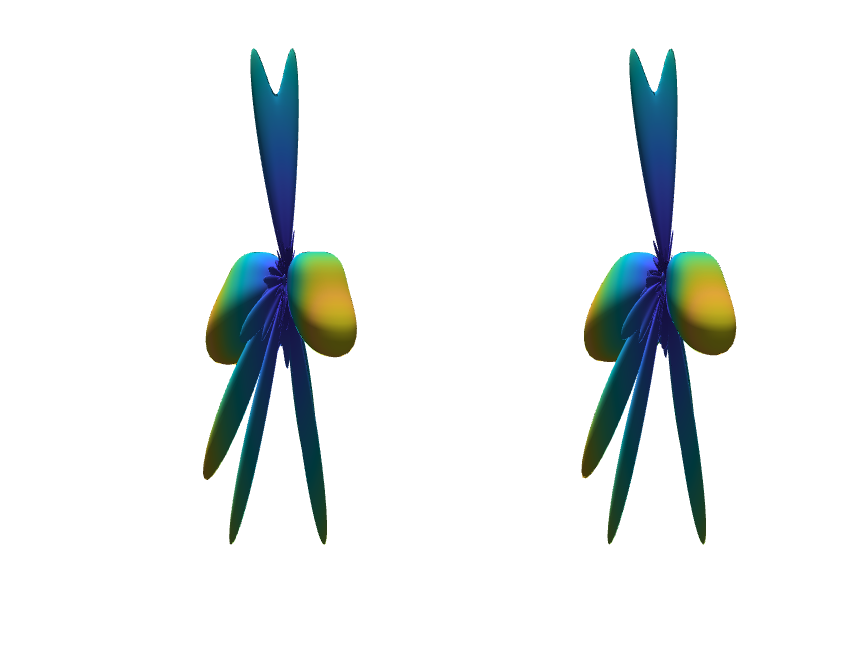


Fig=figure;

% Plot beampatern of Novel Alogorithm
subplot(1,2,1);
Plot3DBeam(F_Nov,Tx);
ax1=gca;
% ax1.Units='centimeters';
% ax1.Position = [ax1.TightInset(1) 2*ax1.TightInset(2) 6 6];
ax1.Title.String='Beampattern of New Structure';
ax1.Title.Interpreter='latex';
ax1.FontSize = 20;
Title='Beampattern of New Structure';

% Plot Optimum beampatern
subplot(1,2,2)
Plot3DBeam(F_Dig,Tx);
ax=gca;
% ax.Units='centimeters';
% ax.Position = [ax1.Position(1)+ax1.Position(3)+ax1.TightInset(3)+ax.TightInset(1)  2*ax.TightInset(2) 6 6];
ax.Title.String='Beampattern of Optimal Digital beamforming';
ax.Title.Interpreter='latex';
ax.FontSize = 20;